## Equazioni Normali: Metodi Iterativi a Confronto

Quando cerchiamo di fittare dei dati con un modello matematico, ci troviamo spesso di fronte a un sistema lineare del tipo $A\;x=b$. Nella maggior parte delle applicazioni pratiche, questo sistema è **sovradeterminato**, ovvero il numero di equazioni m è strettamente maggiore del numero di incognite n. In queste condizioni, in generale, non esiste un vettore x che soddisfi esattamente l'equazione $A\;x-b=0$.  

Per aggirare il problema, cerchiamo la "migliore" soluzione possibile minimizzando il residuo, ovvero cerchiamo un x tale che la norma $ $\vert{}\vert{}Ax-b\vert{}\vert{}_2$$ sia la più piccola possibile. Matematicamente, minimizzare questa quantità (o il suo quadrato) equivale a risolvere il sistema delle **Equazioni Normali**:   


$$A^T A\;x=A^T b$$


Questo passaggio è cruciale per un motivo fondamentale: la nuova matrice del sistema, $A^T A$, è per costruzione quadrata e simmetrica. Affinché $A^T A$ sia strettamente Definita Positiva, è condizione necessaria e sufficiente che la matrice originale A abbia **rango pieno per colonne**, ovvero che le sue colonne siano linearmente indipendenti. Questa proprietà ci apre le porte ai **metodi iterativi di ottimizzazione**, in particolare i metodi di tipo gradiente. Risolvere il sistema delle Equazioni Normali tramite metodi diretti (come l'eliminazione di Gauss) diventa proibitivo per memoria e tempi di calcolo quando si affrontano problemi di grandi dimensioni. 

Tuttavia, il passaggio al sistema normale nasconde un'insidia numerica gravissima: il numero di condizionamento della nuova matrice è pari al quadrato di quello originale.

L'obiettivo di questo progetto è analizzare matematicamente e sperimentalmente come tre diversi metodi iterativi (Gradiente Classico, Gradiente Coniugato e Gradiente Coniugato Precondizionato) reagiscono a questa sfida numerica. Dopo un'analisi delle prestazioni e uno stress-test sul mal condizionamento, chiuderemo il progetto applicando il metodo più adatto a un caso visivo di regressione lineare.

Poniamo H = $A^T A$. H SPD è una proprietà fondamentale nell'algebra lineare numerica, perché ci garantisce che la risoluzione del sistema lineare $H\;x=A^{T\;} b$ è matematicamente equivalente a trovare il punto di minimo globale della funzione quadratica:  


$$$$\Phi(x)=\frac{1}{2}(x,Hx)-(A^Tb,x)$$$$


**Metodo del Gradiente (Discesa Massima)**

L'approccio più intuitivo è il Metodo del Gradiente. L'idea è semplice: partiamo da un punto iniziale $x_0$ e ci muoviamo lungo la direzione di "massima discesa". Per una funzione quadratica, la direzione di massima discesa corrisponde esattamente al residuo del sistema lineare: $$$r^k = -\nabla\Phi(x^k) = A^Tb - Hx^k$$$

Sebbene garantisca una discesa a ogni passo, questo metodo costringe ogni nuova direzione a essere ortogonale solo alla precedente. Se le curve di livello della funzione sono molto ellittiche (cioè se la matrice è mal condizionata), il metodo rimbalza da una parete all'altra della "valle", avanzando lentissimamente verso il minimo con un tipico andamento a zig-zag.

function [x1, ktot, res_storia] = gradiente(A, b, Tol)
 
    x0 = b; %prova iniziale
    ITMAX = 10000;
    res = zeros(ITMAX, 1); 
    
    rk = b - A * x0; % Residuo iniziale (corrisponde alla direzione di discesa)
    res(1) = norm(rk);
    
    k = 1;
    % Criterio di arresto sul residuo relativo 
    while (res(k) > Tol * res(1) && k < ITMAX)
        Ark = A * rk;
        
        % Calcolo del passo alpha lungo la direzione
        alpha = (rk' * rk) / (rk' * Ark);
        
        % Aggiornamento della soluzione
        x1 = x0 + alpha * rk;
        
        % Preparazione per l'iterazione successiva
        x0 = x1;
        rk = rk - alpha * Ark; % Nuovo residuo
        
        k = k + 1;
        res(k) = norm(rk);
    end
    
    res_storia = res(1:k);
    ktot = k - 1;
end

**Metodo del Gradiente Coniugato (CG)**

Il Gradiente Coniugato rappresenta un vero e proprio salto di qualità. Invece di muoversi seguendo direzioni localmente ottimali ma globalmente miopi, il metodo sceglie direzioni di ricerca $p^k$ che sono **H-ortogonali** tra loro.  

Costruendo una base di direzioni coniugate, l'algoritmo non disfa mai il lavoro fatto nelle iterazioni precedenti. In aritmetica esatta, questo garantisce teoricamente di raggiungere la soluzione esatta in un massimo di n passi (dove n è la dimensione del sistema). Nella pratica del computer, ogni operazione di macchina subisce un microscopico errore di troncamento. A causa dell'accumulo di questi minuscoli errori, dopo poche iterazioni le direzioni calcolate **perdono l'ortogonalità teorica**. Se A è ben condizionata, gli errori pesano pochissimo, altrimenti l'amplificazione dell'errore è molto violenta.

function [x1, ktot, res_storia] = GradienteConiugato(A, b, Tol)
    
    x0 = b; 
    ITMAX = 10000;
    res = zeros(ITMAX, 1); 
    
    rk = b - A * x0; % Residuo iniziale
    pk = rk;         % Prima direzione di discesa
    res(1) = norm(rk);
    
    k = 1;
    while (res(k) > Tol * res(1) && k < ITMAX)
        Apk = A * pk; % Operazione più costosa
        
        % Calcolo del passo alpha lungo la direzione pk
        alpha = (rk' * rk) / (pk' * Apk); 
        
        % Aggiornamento della soluzione
        x1 = x0 + alpha * pk;
        
        % Aggiornamento del residuo 
        rkp = rk - alpha * Apk;
        
        % Calcolo del coefficiente beta per l'ortogonalizzazione 
        %beta = (rkp' * Apk) / (Apk' * pk); 
        % versione classica ma meno efficiente e pk con il meno
        %versione più efficiente
        beta = (rkp' * rkp) / (rk' * rk);
        

        % Calcolo della nuova direzione coniugata
        pk = rkp + beta * pk; 
        
        % Preparazione per iterazione successiva
        rk = rkp;
        x0 = x1;
        
        k = k + 1;
        res(k) = norm(rk);
    end
    
    res_storia = res(1:k);
    ktot = k - 1;
end

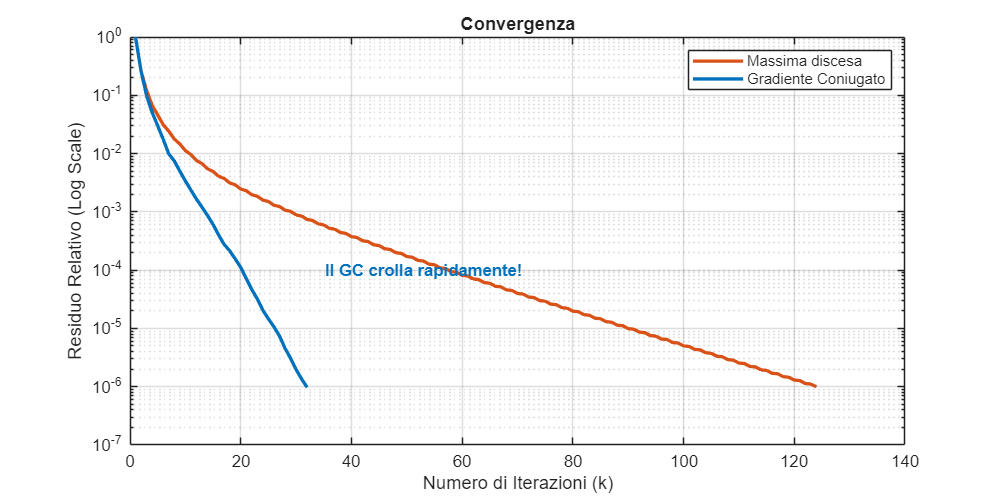

% Mostriamo efficienza e facciamo confronto tra i due metodi
Tol = 1e-6; % Tolleranza per il criterio di arresto
dimensioni_n = [50, 100, 250, 500]; %incognite (n)
dimensioni_m = dimensioni_n * 2; %equazioni (m > n)

% Vettori per salvare i risultati totali
iter_g = zeros(length(dimensioni_n), 1);
iter_gc = zeros(length(dimensioni_n), 1);
tempi_g = zeros(length(dimensioni_n), 1);
tempi_gc = zeros(length(dimensioni_n), 1);
iter_g_std = zeros(length(dimensioni_n), 1);
iter_gc_std = zeros(length(dimensioni_n), 1);

rng(1);

n_trials = 15;

for i = 1:length(dimensioni_n)
    %a ogni giro del ciclo fa prova con n e m più grandi
    n = dimensioni_n(i); m = dimensioni_m(i);

    iter_g_t = zeros(n_trials,1); iter_gc_t = zeros(n_trials,1);
    tempi_g_t = zeros(n_trials,1); tempi_gc_t = zeros(n_trials,1);

    %faccio più test e grafico la media dei tempi e delle iterazioni
    %ottenuta per i diversi n
    for t = 1:n_trials
        % Generazione di un problema casuale
        A_test = randn(m,n);
        b_test = randn(m,1);
        %non devo controllare che A abbia rango pieno (e che quindi A^TA SPD)
        %perché le matrici generate casualmente con distribuzioni continue come
        % randn hanno rango massimo con probabilità 1
        %passo alle eq normali
        H = A_test'*A_test;
        d = A_test'*b_test;

        %gradiente classico
        %uso tilde perchè non prendiamo la soluzione ma la performance
        tic; [~, iter_g_t(t), res_g] = gradiente(H,d,Tol);
        tempi_g_t(t) = toc;

        %Gradiente coniugato
        tic; [~, iter_gc_t(t), res_gc] = GradienteConiugato(H,d,Tol);
        tempi_gc_t(t) = toc;

        % Se siamo alla dimensione n=250, salviamo i residui della prima
        % ripetizione per il grafico di convergenza
        if n == 250 && t == 1
            res_g_plot = res_g;
            res_gc_plot = res_gc;
        end
    end

    iter_g(i) = mean(iter_g_t); iter_g_std(i) = std(iter_g_t);
    iter_gc(i) = mean(iter_gc_t); iter_gc_std(i) = std(iter_gc_t);
    tempi_g(i) = mean(tempi_g_t); tempi_gc(i) = mean(tempi_gc_t);
end

% 1. Grafico della Convergenza (Residuo Relativo) per n=250
figure('Name', 'Analisi di Convergenza', 'Position', [100, 100, 800, 400]);
semilogy(1:length(res_g_plot), res_g_plot / res_g_plot(1), 'LineWidth', 2, 'Color', '#D95319');
hold on;
semilogy(1:length(res_gc_plot), res_gc_plot / res_gc_plot(1), 'LineWidth', 2, 'Color', '#0072BD');
grid on;
title('Convergenza');
xlabel('Numero di Iterazioni (k)');
ylabel('Residuo Relativo (Log Scale)'); %||r_k|| / ||r_0||
legend('Massima discesa', 'Gradiente Coniugato', 'Location', 'northeast');
text(length(res_gc_plot)*1.1, 1e-4, 'Il GC crolla rapidamente!', 'Color', '#0072BD', 'FontWeight', 'bold');

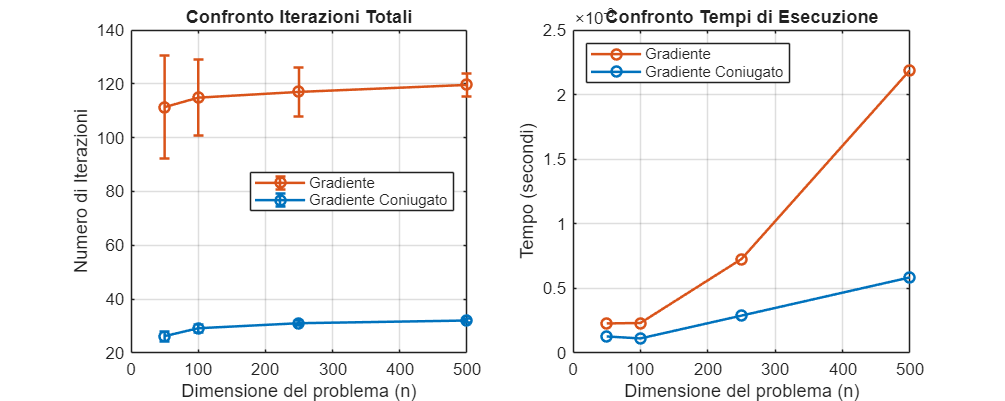


% 2. Confronto Iterazioni (media su n_trials con barre d'errore)
figure('Name', 'Confronto Prestazioni', 'Position', [150, 150, 1000, 400]);

subplot(1,2,1);
errorbar(dimensioni_n, iter_g, iter_g_std, '-o', 'LineWidth', 1.5, 'Color', '#D95319');
hold on;
errorbar(dimensioni_n, iter_gc, iter_gc_std, '-o', 'LineWidth', 1.5, 'Color', '#0072BD');
title('Confronto Iterazioni Totali');
xlabel('Dimensione del problema (n)');
ylabel('Numero di Iterazioni');
legend('Gradiente', 'Gradiente Coniugato', 'Location', 'east');
grid on;

% 3. Confronto Tempi di Esecuzione (media su n_trials run)
subplot(1,2,2);
plot(dimensioni_n, tempi_g, '-o', 'LineWidth', 1.5, 'Color', '#D95319');
hold on;
plot(dimensioni_n, tempi_gc, '-o', 'LineWidth', 1.5, 'Color', '#0072BD');
title('Confronto Tempi di Esecuzione');
xlabel('Dimensione del problema (n)');
ylabel('Tempo (secondi)');
legend('Gradiente', 'Gradiente Coniugato', 'Location', 'northwest');
grid on;

Fino ad ora abbiamo visto che il Gradiente Coniugato è più veloce, ma perché non usare semplicemente metodi diretti (come l'eliminazione di Gauss) per risolvere il sistema?

Le risposte sono due: il costo computazionale per iterazione e il condizionamento.

Un metodo diretto come QR  richiede $O\left({m\;n}^2 \right)$operazioni per fattorizzare H una sola volta. Un metodo iterativo richiede solo $O\left(n^2 \right)$ operazioni (un prodotto matrice-vettore) per ogni iterazione. Un ulteriore vantaggio, che qui non verifichiamo sperimentalmente, è la preservazione della sparsità nelle applicazioni con matrici sparse

La velocità di convergenza dei metodi iterativi dipende dal **numero di condizionamento** della matrice $\kappa(A)=\frac{\sigma_{max}}{\sigma_{min}}$. Geometricamente, un alto condizionamento significa che le curve di livello della nostra funzione quadratica $\phi \left(x\right)$ non sono cerchi perfetti, ma ellissi estremamente allungate, simili a gole strette e ripide.

Qui sorge il grande svantaggio di usare il metodo delle Equazioni Normali per risolvere la regressione. Come dimostrato analizzando i valori singolari, il condizionamento della matrice del sistema normale è pari al quadrato del condizionamento della matrice originale:


$$$$\kappa(A^T A) = \kappa(A)^2$$$$


Questo significa che se la nostra matrice dati A è anche solo leggermente mal condizionata (es. $$\kappa(A) = 10^3$$), il sistema che andiamo a risolvere avrà un condizionamento disastroso ($$\kappa(A^TA) = 10^6$$).

In queste condizioni estreme, il Metodo del Gradiente classico va in "crisi totale", rimbalzando all'infinito tra le pareti della gola senza avanzare verso il minimo (fenomeno dello zig-zag). Il Gradiente Coniugato, grazie alle sue direzioni H-ortogonali, riesce invece a mitigare questo effetto e a trovare la soluzione.

Se il condizionamento del sistema normale $$\kappa(A^T A)$$ diventa troppo elevato, anche il Gradiente Coniugato standard inizia a mostrare i suoi limiti numerici, rallentando la convergenza. Per risolvere questo problema alla radice si utilizza il precondizionamento.

L'idea fondamentale è quella di trasformare il sistema lineare originario $H\;x=c$ in un sistema equivalente che abbia lo stesso punto di minimo, ma un numero di condizionamento decisamente più piccolo. Matematicamente, scegliamo una matrice M (il precondizionatore) che sia SPD e risolviamo il sistema modificato (precondizionamento a sinistra):


$$$$M^{-1}Hx = M^{-1}c$$$$


Affinché l'algoritmo sia efficiente nel calcolo computazionale, la matrice M deve soddisfare due requisiti:

- M deve approssimare bene la matrice H. Idealmente, vorremmo $$\kappa(M^{-1}H) \approx 1$.$

- Risolvere un sistema lineare del tipo $$M z = r$$ (operazione richiesta a ogni iterazione del nuovo algoritmo) deve essere estremamente "economico" in termini di tempo di calcolo e memoria.

Nel nostro caso, per mantenere l'algoritmo leggero e lineare, utilizzeremo il precondizionatore di Jacobi. La matrice M viene definita semplicemente come la diagonale principale della matrice del sistema:


$$$$M = \text{diag}(H)$$$$


Questa scelta è straordinariamente economica: l'inversione di M non richiede fattorizzazioni complesse, ma si riduce a una banale divisione elemento per elemento per i coefficienti diagonali. Nonostante la sua semplicità, il precondizionatore di Jacobi è in grado di riscalare le componenti del sistema, abbattendo drasticamente il numero di iterazioni necessarie quando le variabili presentano scale numeriche molto differenti.

function [x1, ktot, res_storia] = GradienteConiugatoPrecondizionato(A, b, Tol)
    x0 = b; 
    ITMAX = 10000;
    res = zeros(ITMAX,1);
    rk = b - A*x0;
    
    % Definizione del precondizionatore di Jacobi (M è la diagonale di A)
    M = diag(diag(A)); 
    
    % Risoluzione del sistema ausiliario lineare del precondizionatore (facile perché M è diagonale)
    zk = rk ./ diag(M); 
    pk = zk; %la prima dir è z0
    
    res(1) = norm(rk);
    k = 1;
    while (res(k) > Tol*res(1) && k < ITMAX)
        Apk = A*pk;
        
        % Il passo alpha cambia leggermente usando zk:
        %il numeratore usa il prodotto scalare tra residuo e residuo precondizionato, non residuo con se stesso
        alpha = (rk'*zk) / (pk'*Apk);
        x1 = x0 + alpha*pk;
        rkp = rk - alpha*Apk; %aggiorno residuo vero
        
        % Nuovo passo di precondizionamento (risolto come prima)
        %M*z(k+1) = (rk+1)
        zkp = rkp ./ diag(M);
        
        % Calcolo del coefficiente beta modificato
        beta = (zkp' * rkp) / (zk' * rk);
        pk = zkp + beta*pk; %La nuova direzione coniugata si costruisce a partire da zk+1
        
        x0 = x1;
        rk = rkp;
        zk = zkp;
        k = k + 1;
        res(k) = norm(rk);
    end
    res_storia = res(1:k);
    ktot = k - 1;
end


Al fine di valutare la robustezza e i limiti di convergenza degli algoritmi di ottimizzazione, l'analisi si concentrerà su uno scenario estremamente frequente nei contesti applicativi reali, come la Data Science o la modellistica ingegneristica. In questi ambiti, la matrice del sistema A rappresenta tipicamente un dataset grezzo, in cui ogni colonna modella una specifica *feature* o variabile fisica (ad esempio: età, stipendi, misurazioni in millimetri e in chilometri).

Queste grandezze sono intrinsecamente caratterizzate da unità di misura eterogenee e, di conseguenza, assumono valori numerici con ordini di grandezza radicalmente differenti. Per simulare in modo fedele e rigoroso l'elaborazione di un dataset non standardizzato, la matrice dei coefficienti A è stata costruita partendo da una base di dati generati casualmente (rumore gaussiano), per poi post-moltiplicarla per una matrice diagonale di scalatura (implementata tramite una distribuzione logaritmica dei pesi). Questa operazione distrugge volutamente l'omogeneità numerica delle colonne, simulando la presenza di variabili che spaziano su molteplici ordini di grandezza.

Questo passaggio costruttivo è di cruciale importanza per l'obiettivo del nostro test. Quando si passa al sistema delle Equazioni Normali, il mal condizionamento indotto dalle differenze di scala viene elevato al quadrato, deformando pesantemente il paraboloide dell'errore, che assume la geometria di una valle estremamente stretta e allungata. È esattamente in questo scenario avverso che il Precondizionatore di Jacobi esprime il suo massimo potenziale pratico: estraendo e invertendo la diagonale principale del sistema, esso agisce di fatto come un operatore automatico di *Feature Scaling*. Normalizzando implicitamente le grandezze in gioco, Jacobi ripristina la simmetria dello spazio di ricerca, permettendo al Gradiente Coniugato Precondizionato (PCG) di scavalcare il problema della scala e di abbattere drasticamente il numero di iterazioni necessarie per raggiungere la convergenza.

rng(42);
m_cond = 500; % Numero di osservazioni (es. righe del dataset)
n_cond = 200; % Numero di variabili/feature (es. colonne)

% 1. Creiamo un dataset generico puramente casuale.
A_base = randn(m_cond, n_cond);

% 2. Simuliamo le diverse unità di misura 
% Moltiplichiamo le colonne in modo che la prima abbia valori piccoli (es. 1)
% e l'ultima valori molto grandi (es. 1000)
scale_colonne = logspace(0, 3, n_cond);
A_cond = A_base * diag(scale_colonne);

% Generazione termine noto casuale
b_cond = randn(m_cond, 1);
Tol_cond = 1e-6;



Condizionamento della matrice originale K(A): 1.37e+03


fprintf('Condizionamento della matrice originale K(A): %.2e\n', cond(A_cond));

% 2. Passiamo alle Equazioni Normali (H = A'*A)
%Il condizionamento diventerà il quadrato
H_cond = A_cond' * A_cond;
c_cond = A_cond' * b_cond;


Condizionamento del sistema normale K(A^T*A): 1.87e+06 (Peggiore al quadrato!)


fprintf('Condizionamento del sistema normale K(A^T*A): %.2e (Peggiore al quadrato!)\n', cond(H_cond));

% 3. Testiamo gli algoritmi
tic;
[x_g_cond, iter_g_cond, res_g_cond] = gradiente(H_cond, c_cond, Tol_cond);
tempo_g_cond = toc;

tic;
[x_gc_cond, iter_gc_cond, res_gc_cond] = GradienteConiugato(H_cond, c_cond, Tol_cond);
tempo_gc_cond = toc;

tic;
[x_pcg_cond, iter_pcg_cond, res_pcg_cond] = GradienteConiugatoPrecondizionato(H_cond, c_cond, Tol_cond);
tempo_pcg_cond = toc;


Gradiente Classico: 6315 iterazioni (Tempo: 0.0357 s)


fprintf('Gradiente Classico: %d iterazioni (Tempo: %.4f s)\n', iter_g_cond, tempo_g_cond);

Gradiente Coniugato: 163 iterazioni (Tempo: 0.0033 s)


fprintf('Gradiente Coniugato: %d iterazioni (Tempo: %.4f s)\n', iter_gc_cond, tempo_gc_cond);

Gradiente Coniugato Precondizionato: 24 iterazioni (Tempo: 0.0078 s)


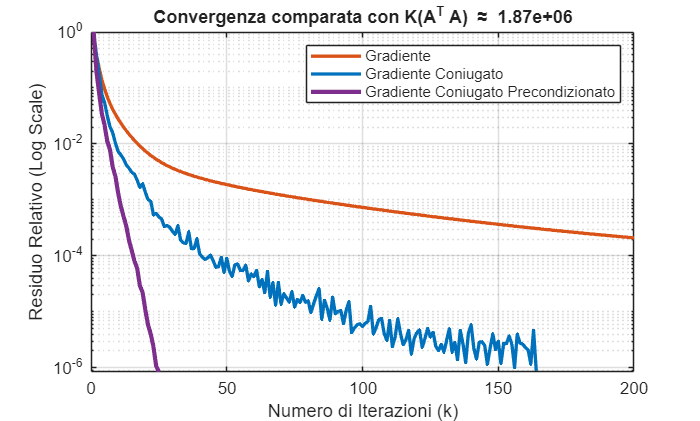

fprintf('Gradiente Coniugato Precondizionato: %d iterazioni (Tempo: %.4f s)\n', iter_pcg_cond, tempo_pcg_cond);

% La crisi del gradiente e la cura del precondizionamento
figure('Name', 'Effetto del Mal Condizionamento e Precondizionamento');

% 1. Curva Gradiente Classico
semilogy(1:length(res_g_cond), res_g_cond / res_g_cond(1), 'LineWidth', 2, 'Color', '#D95319');
hold on;

% 2. Curva Gradiente Coniugato
semilogy(1:length(res_gc_cond), res_gc_cond / res_gc_cond(1), 'LineWidth', 2, 'Color', '#0072BD');

% 3. Curva Gradiente Coniugato Precondizionato
semilogy(1:length(res_pcg_cond), res_pcg_cond / res_pcg_cond(1), 'LineWidth', 2.5, 'Color', '#7E2F8E');

xlim([0,200])
grid on;
title(sprintf('Convergenza comparata con K(A^T A) \\approx %.2e', cond(H_cond)));
xlabel('Numero di Iterazioni (k)');
ylabel('Residuo Relativo (Log Scale)');

legend('Gradiente ', ...
       'Gradiente Coniugato', ...
       'Gradiente Coniugato Precondizionato', ...

       'Location', 'northeast');

Il test di condizionamento eseguito ha messo in luce in modo empirico e inequivocabile la differenza prestazionale, computazionale e teorica tra i tre metodi iterativi analizzati. L'introduzione del problema a scale numeriche differenziate ha esaltato i punti di forza e le debolezze di ciascun approccio:

- **Il Gradiente Classico (Massima Discesa):** Si conferma l'anello debole in presenza di forte mal condizionamento. L'algoritmo risente pesantemente del fenomeno dello zig-zag, rimanendo intrappolato in un numero altissimo di iterazioni (spesso raggiungendo il limite massimo ITMAX) senza riuscire a convergere alla tolleranza richiesta. Dal punto di vista geometrico, le curve di livello estremamente allungate (ellissoidi schiacciati) fanno sì che il vettore gradiente punti quasi ortogonalmente rispetto alla direzione del minimo reale.

- **Il Gradiente Coniugato Standard (CG):** Mostra un netto passo avanti rispetto al gradiente classico. Sfruttando le direzioni $H$-coniugate, non ripete mai gli stessi errori e "buca" le curve di livello in modo molto più diretto. Tuttavia, sebbene sia teoricamente robusto, quando il mal condizionamento è causato da forti differenze di scala tra i dati (come simulato nel nostro test), il CG standard subisce comunque un marcato rallentamento, richiedendo un numero di iterazioni non trascurabile per raggiungere la convergenza.

- **Il Gradiente Coniugato Precondizionato (PCG):** Rappresenta la vera svolta ingegneristica del progetto. L'applicazione del precondizionatore di Jacobi agisce direttamente sulla geometria del problema operando una sorta di *Feature Scaling* automatico. Riscalando le componenti della matrice H, esso "arrotonda" le curve di livello del paraboloide, ripristinando la simmetria dello spazio. Come evidenziato dal grafico di convergenza, la curva del PCG crolla verticalmente verso la tolleranza impostata in una frazione minima delle iterazioni rispetto al CG classico.

**APPLICAZIONE PRATICA: RISOLUZIONE PROBLEMA DI REGRESSIONE LINEARE**

Per visualizzare concretamente l'obiettivo matematico alla base delle Equazioni Normali studiate finora, applichiamo i concetti a un classico problema di regressione lineare bidimensionale. Generiamo un set di dati sintetici affetti da rumore e utilizziamo l'algoritmo del Gradiente Coniugato classico per trovare la retta di regressione. In questo scenario specifico (dimensione del sistema n=2 e condizionamento basso $$\kappa \approx 138$$), l'utilizzo del precondizionatore risulta computazionalmente superfluo. La teoria garantisce infatti che il GC standard converga alla soluzione esatta in un numero di iterazioni pari al massimo alla dimensione del sistema 

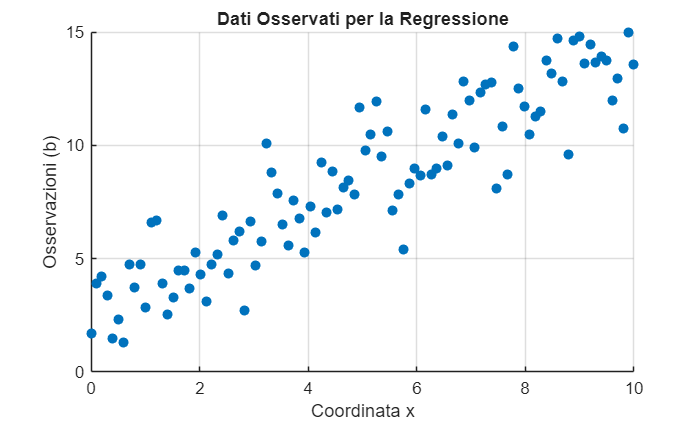

%generiamo i dati per il problema di regressione
clear; clc; close all;
rng(42); %seed fissato

% 1. Generazione dei dati 
%per facilità, li mettiamo su una retta con rumore gaussiano
m = 100; %numero di osservazioni (punti)(equazioni)
n = 2;   %Numero di parametri (incognite: intercetta e pendenza di una retta y=cx+q)

%per generare la coord x dei nostri dati tra 0 e 10
X_data = linspace(0, 10, m)'; 

% Creiamo la matrice A (mat di design)
A = [ones(m, 1), X_data]; 
%colonna di uni per q e colonna di x per c:
%yi = 1*qi + xi*ci

%i nostri dati generati si basano su una retta con rumore
parametri_veri = [2.5; 1.2]; %y=1.2x+2.5
%genera un vett col di 100 numeri casuali gaussiani
rumore = randn(m, 1) * 1.5; 

%Calcola i valori della coordinata y 
%genera la retta perfetta e ci somma il rumore 
b = A * parametri_veri + rumore;

% Visualizziamo i dati
figure;
scatter(X_data, b, 'filled', 'MarkerFaceColor', '#0072BD');
title('Dati Osservati per la Regressione');

xlabel('Coordinata x');
ylabel('Osservazioni (b)');
grid on;

% 2. Costruzione del sistema delle Equazioni Normali
% Calcoliamo A^T * A e A^T * b
A_T = A';
H_prova = A_T * A;    
b_norm = A_T * b;


Asimmetria numerica di H (dovrebbe essere ~0, ordine epsilon macchina): 0.00e+00


% Verifichiamo H simmetrica
%è garantito algebricamente

   1.0e+03 *

    0.0248
    3.4253



fprintf('Asimmetria numerica di H (dovrebbe essere ~0, ordine epsilon macchina): %.2e\n', norm(H_prova - H_prova', 'fro'));
%Verifichiamo che H sia SPD
disp(eig(H_prova))
%tolleranza più stringente della solita per più precisione
Tol_finale = 1e-8;

% Risolviamo le eq normali iniziali con il gradiente coniugato
[parametri_ottimali, iter_finali, res_finali] = GradienteConiugato(H_prova, b_norm, Tol_finale);

intercetta_calcolata = parametri_ottimali(1);

Parametri VERI: Intercetta = 2.50, Pendenza = 1.20


pendenza_calcolata = parametri_ottimali(2);


Parametri CALCOLATI (GC in 2 iterazioni): Intercetta = 2.66, Pendenza = 1.15


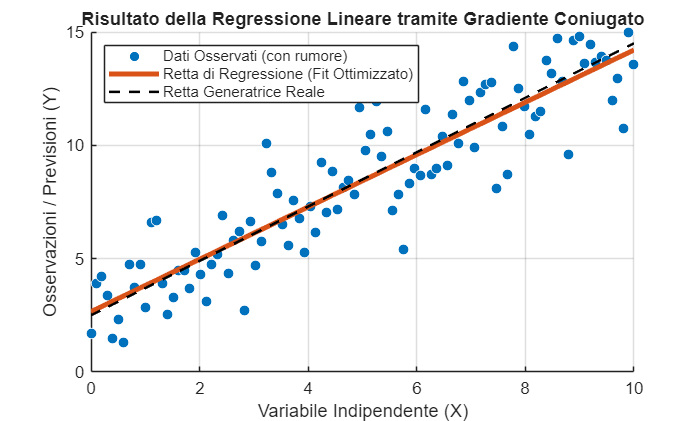

fprintf('Parametri VERI: Intercetta = %.2f, Pendenza = %.2f\n', parametri_veri(1), parametri_veri(2));
fprintf('Parametri CALCOLATI (GC in %d iterazioni): Intercetta = %.2f, Pendenza = %.2f\n', ...
        iter_finali, intercetta_calcolata, pendenza_calcolata); 
%qui n=2, e infatti il metodo termina in 2 iterazioni, esattamente il bound teorico

% Usiamo i parametri appena trovati per calcolare i valori previsti dal nostro modello
y_fit = A * parametri_ottimali;

%grafico finale dei dati e del modello
figure('Name', 'Fit di Regressione Lineare Finale');
% punti dati originali
scatter(X_data, b, 40, 'filled', 'MarkerFaceColor', '#0072BD', 'MarkerEdgeColor', 'w', 'DisplayName', 'Dati Osservati (con rumore)');
hold on;

%retta trovata con il nostro algoritmo
plot(X_data, y_fit, 'LineWidth', 3, 'Color', '#D95319', 'DisplayName', 'Retta di Regressione (Fit Ottimizzato)');

%retta generatrice "perfetta" per vedere quanto ci siamo avvicinati
plot(X_data, A * parametri_veri, '--k', 'LineWidth', 1.5, 'DisplayName', 'Retta Generatrice Reale');

grid on;
title('Risultato della Regressione Lineare tramite Gradiente Coniugato');

xlabel('Variabile Indipendente (X)');
ylabel('Osservazioni / Previsioni (Y)');
legend('Location', 'northwest');